s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = (s+5)/(s*(s-5))

G =
 
    s + 5
  ---------
  s^2 - 5 s
 
Continuous-time transfer function.



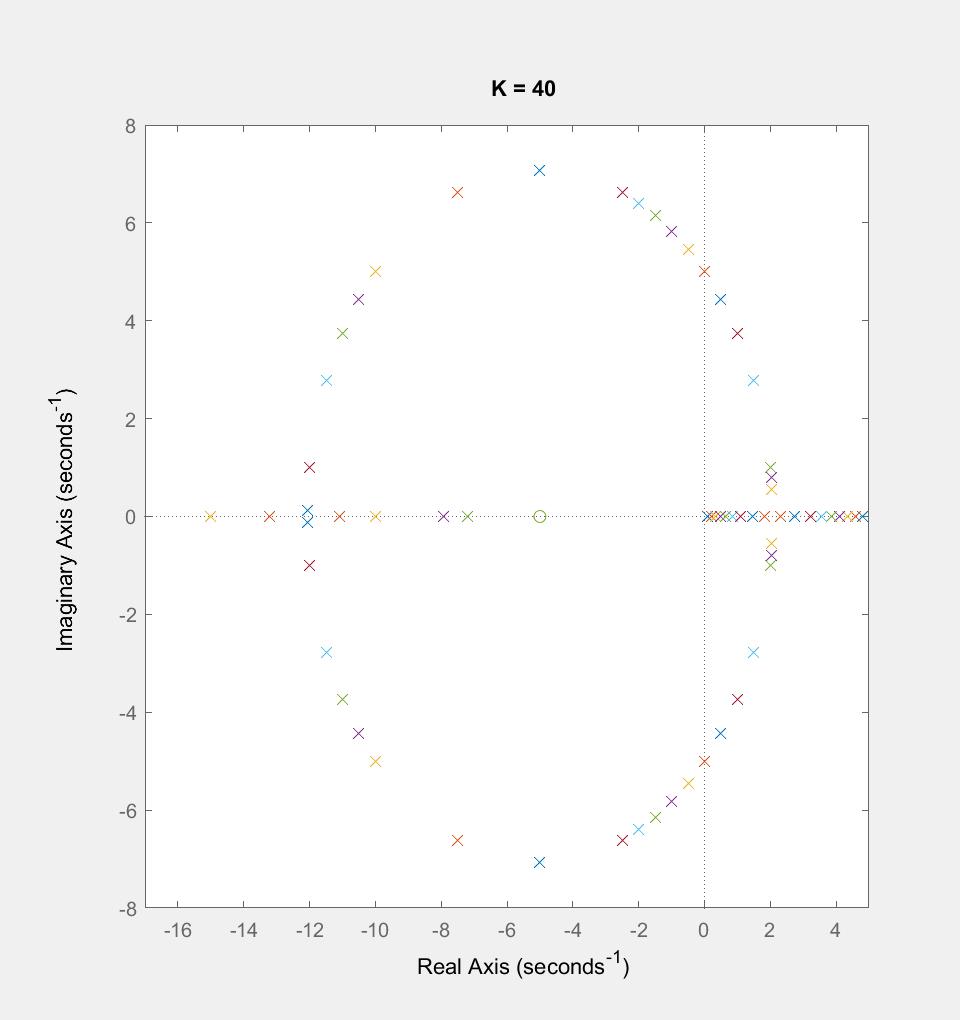


lista_K = [0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.85 0.9 0.95 ...
    1 2 3 4 5 6 7 8 9 10 15 20 25 26 27 28 29 29.14 29.3 30 35 40];

set(gcf,'Visible','on')
for K = lista_K
    T = feedback(G*K, 1);
    pzmap(T), hold on;
    axis([-17     5    -8     8])
    title(sprintf('K = %g', K));
    pause(0.1);
end